Reading the Image:

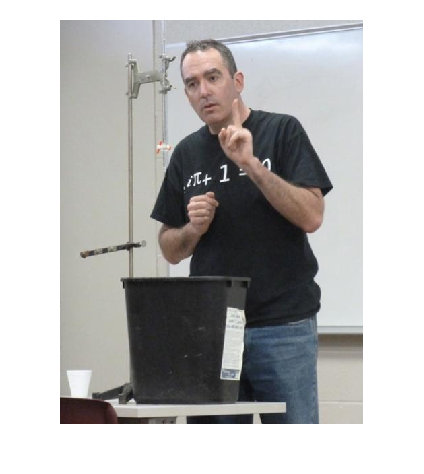

H = imread('Professor_Photo.jpg');
imshow(H); % This will display the original image

Convert to Grayscale :

H_gray = rgb2gray(H);

SVD Decomposition:

[U, S, V] = svd(double(H_gray));

Compress the Image:

k = 50;
H_compressed = U(:, 1:k) * S(1:k, 1:k) * V(:, 1:k)';

Display Compressed Image:

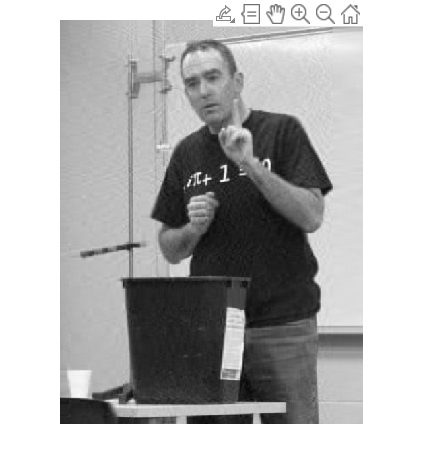

imshow(uint8(H_compressed));

Explanation:

- The function `imread` reads the image from the file.

- `rgb2gray` is used to convert a colored image into grayscale.

- Singular Value Decomposition (SVD) decomposes the image matrix into three matrices `U`, `S`, and `V`. The `S` matrix contains singular values in descending order.

- By selecting only the first `k` singular values (and the corresponding vectors in `U` and `V`), we can approximate the original image. The approximation is of lower rank (and thus compressed) compared to the original image.

- The value of `k` determines the level of compression. A smaller `k` means more compression but also more loss of detail in the image.